# Identificazione in presenza di limitazioni di velocità/posizione massima.

usare c2d(zpk(),st)

Spesso i sistemi meccanici hanno limiti di posizione e velocità massima.

In questo caso, è necessario lavorare con range positivi e negativi.

Tuttavia la presenza dell'attrito statico rende l'approssimazione lineare molto imprecisa quando si lavora con continui cambi di posizione e velocità.

Una soluzione è inserire una "portante", cioè un segnale a bassa frequenza che consente di mantenere la velocità diverse da zero per lunghi tratti.

## Esempio

consideriamo il modello meccanico motore-trasmissione-carico, con trasmissione elastica e presenza di attrito statico.

Il sistema ha un ingresso (la coppia motore), e due uscite (posizione e velocità motore). Ci interessa trovare un modello lineare che approssima la relazione coppia-velocità.

clc;
clear all;
close all;
nome_gruppo = 'GruppoG';
%addpath(['..',filesep,'E:\AUTOMATICA\PROGETTO\rericeviemento']) %aggiunge al path la cartella modelli (che deve essere nella cartella superiore)

model=ElasticRoboticSystem();
model.show;

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


n_output_number=model.getOutputNumber

n_output_number = 4

for i=1:n_output_number
    fprintf('Output %d:    %s\n',i,model.getOutputName{i});
end

Output 1:    position_1
Output 2:    position_2
Output 3:    velocity_1
Output 4:    velocity_2


st=model.getSamplingPeriod;
cs=ControlledSystemScara(model,nome_gruppo);

Kp_q1 = 0.1;
Ki_q1 = 0.1;
Kp_q2 = 0.01;
Ki_q2 = 0.1;
ctrl = ScaraBasicPIController(st, Kp_q1, Ki_q1, Kp_q2, Ki_q2);
ctrl.setUMax(model.getUMax);
cs.setController(ctrl);
omega_portante = 1; %rad/s
ampiezza_portante=250;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))'; %un segnale che varia lentamente nel tempo 
portante=ampiezza_portante*sin(omega_portante*t); %se ho unrapporto di rudizione troppo grande non e' lineare velocita che va solo nella stessa direzione 20% che tanto

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

- il problema se faccio andare per sempre potrebbe schiacciare la fine corsa 

- per cui ho uni segnale che varia lentamenta un po positivo e un po negativo 

- taro l'ampiezza della portante rispetto al segnale piu grande la portante meno cambi di direzione ce l'ho 

- posso sommare coseno non seno 

w0=omega_portante*10; %rad/s 
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=250;

Sommo i due segnali

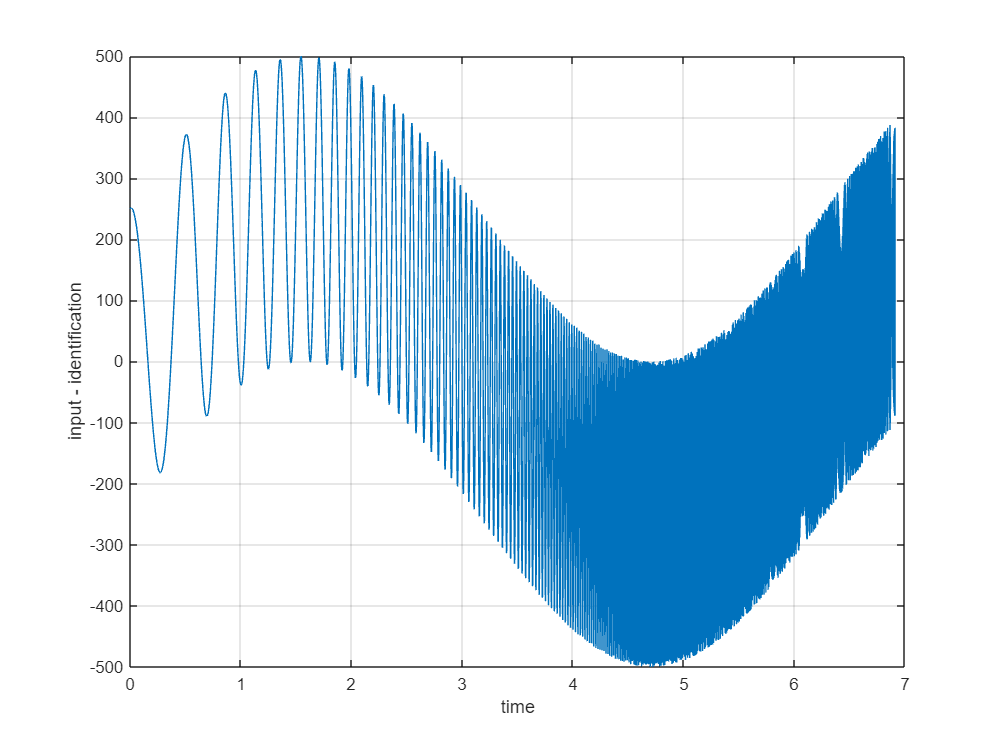

control_action=portante+ control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

Spettrogramma (contenuto frequenziale al variare del tempo)

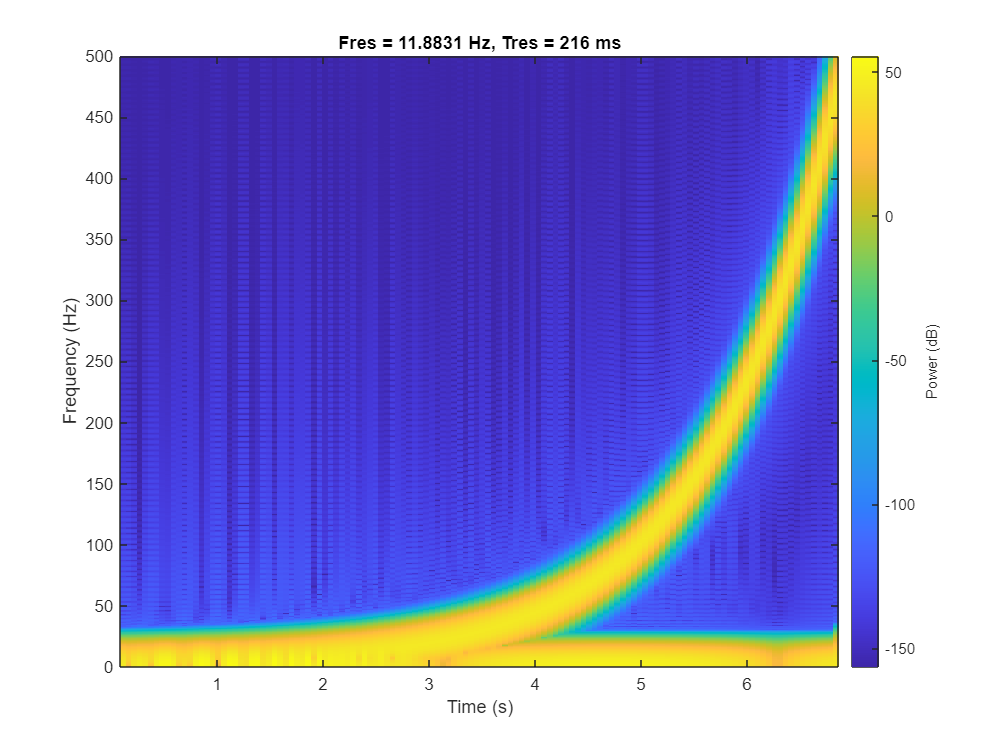

pspectrum(control_action,1/st,'spectrogram'); %uguale come prima l'unicac differenza e'che la portanteche che rappresenta la basse frequenzee la linea sotto

exciting_signal_q1 = zeros(length(t),model.getInputNumber);
exciting_signal_q1(:,1) = control_action;
reference_cl = zeros(length(t),model.getOutputNumber);

cs.initialize 
for idx=1:length(t)
    [process_output_q1(idx,:),control_action_q1(idx,:),t_q1(idx,1)]=cs.step(reference_cl(idx,:)',exciting_signal_q1(idx,:)');  
end
exciting_signal_q2 = zeros(length(t),model.getInputNumber);
exciting_signal_q2(:,2) = control_action;

Simulo il sistema in anello chiuso per l'identificazione del giunto 2.

cs.initialize % reinizializza la simulatione
for idx=1:length(t)
    [process_output_q2(idx,:),control_action_q2(idx,:),t_q2(idx,1)]=cs.step(reference_cl(idx,:)',exciting_signal_q2(idx,:)');  
end

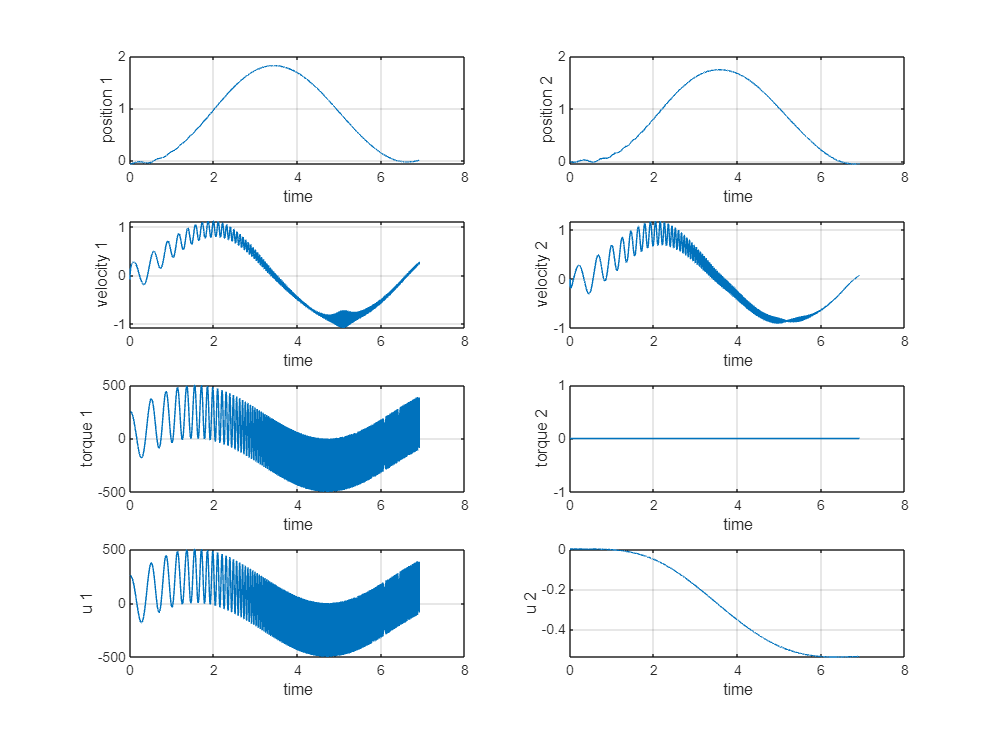

figure
subplot(4,2,1)
plot(t_q1,process_output_q1(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_q1,process_output_q1(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_q1,exciting_signal_q1(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_q1,control_action_q1(:,1))
xlabel('time')
ylabel('u 1')
grid on

subplot(4,2,2)
plot(t_q1,process_output_q1(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_q1,process_output_q1(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_q1,exciting_signal_q1(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_q1,control_action_q1(:,2))
xlabel('time')
ylabel('u 2')
grid on

### Risultati giunto 2

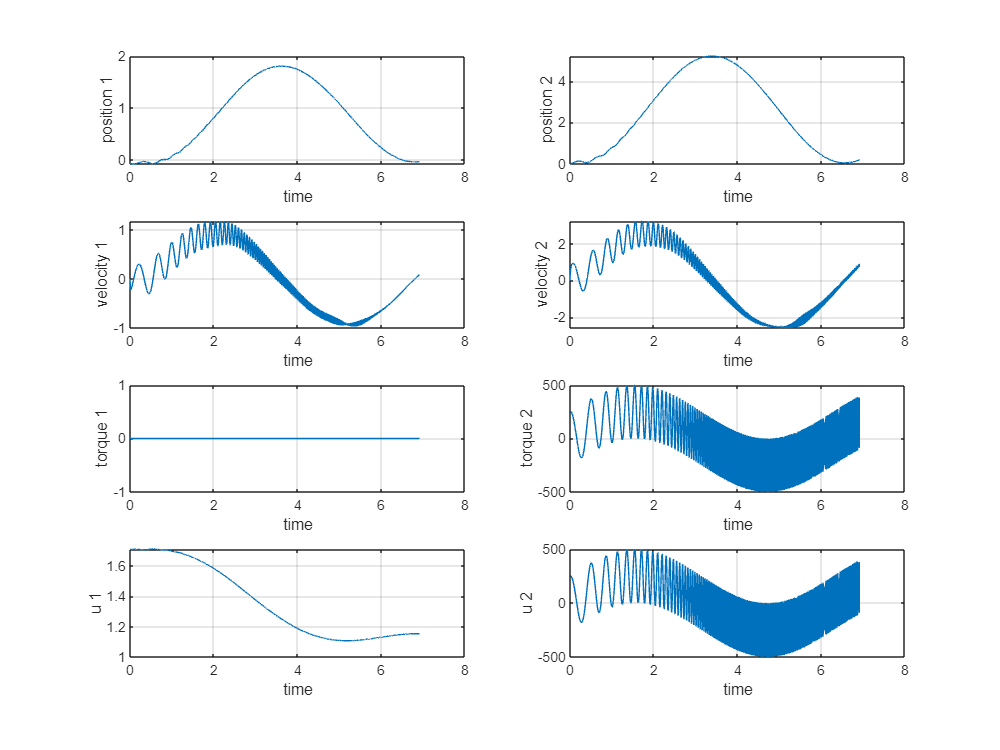

figure
subplot(4,2,1)
plot(t_q2,process_output_q2(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_q2,process_output_q2(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_q2,exciting_signal_q2(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_q2,control_action_q2(:,1))
xlabel('time')
ylabel('u 1')
grid on

subplot(4,2,2)
plot(t_q2,process_output_q2(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_q2,process_output_q2(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_q2,exciting_signal_q2(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_q2,control_action_q2(:,2))
xlabel('time')
ylabel('u 2')
grid on

### Risposta in frequenza

Rappresento la risposta in frequenza ottenuta per i due giunti.

#### Giunto 1

Risposta in frequenza dell'identificazione del giunto 1.

identification_q1 = iddata(process_output_q1(:,3),control_action_q1(:,1),st);
freq_resp_ident_q1 = spafdr(identification_q1);

#### Giunto 2

Risposta in frequenza dell'identificazione del giunto 2.

identification_q2 = iddata(process_output_q2(:,4),control_action_q2(:,2),st);
freq_resp_ident_q2 = spafdr(identification_q2);

#### Diagramma di bode della risposta in frequenza

La linea tratteggiata rossa rappresenta la frequenza iniziale del chirp.

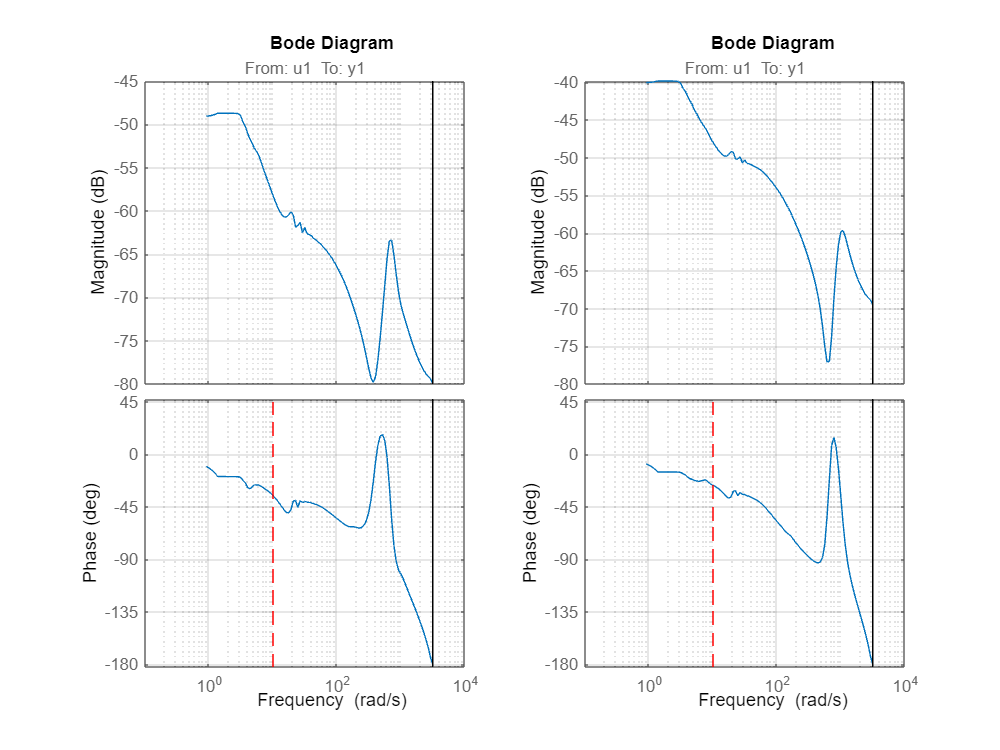

figure
subplot(1,2,1)
bode(freq_resp_ident_q1)
hold on
plot(w0*[1 1],ylim,'--r') 
hold off
grid on

subplot(1,2,2)
bode(freq_resp_ident_q2)
hold on
plot(w0*[1 1],ylim,'--r') 
hold off
grid on

## Stima dei modelli

Stima dei modelli del terzo ordine a partire dai risultati ottenuti sui due giunti.

### Giunto 1

Vengono inseriti dei pesi per effettuare il fitting nelle frequenze di interesse, in particolare tra 100 e 550 rad/s.

peso = ones(length(freq_resp_ident_q1.Frequency),1);

wpeso1_1 = 100;
wpeso1_2 = 1000;

peso(freq_resp_ident_q1.Frequency<wpeso1_1) = 1e-3;
peso(freq_resp_ident_q1.Frequency>wpeso1_2) = 1e-3;   

Stima dei modelli continuo e discreto del primo giunto.

opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
modello_continuo_q1 = ssest(freq_resp_ident_q1, 3, opts);
modello_discreto_q1 = ssest(freq_resp_ident_q1, 3, 'Ts', st, opts);

Confronto con la risposta in frequenza del primo giunto.

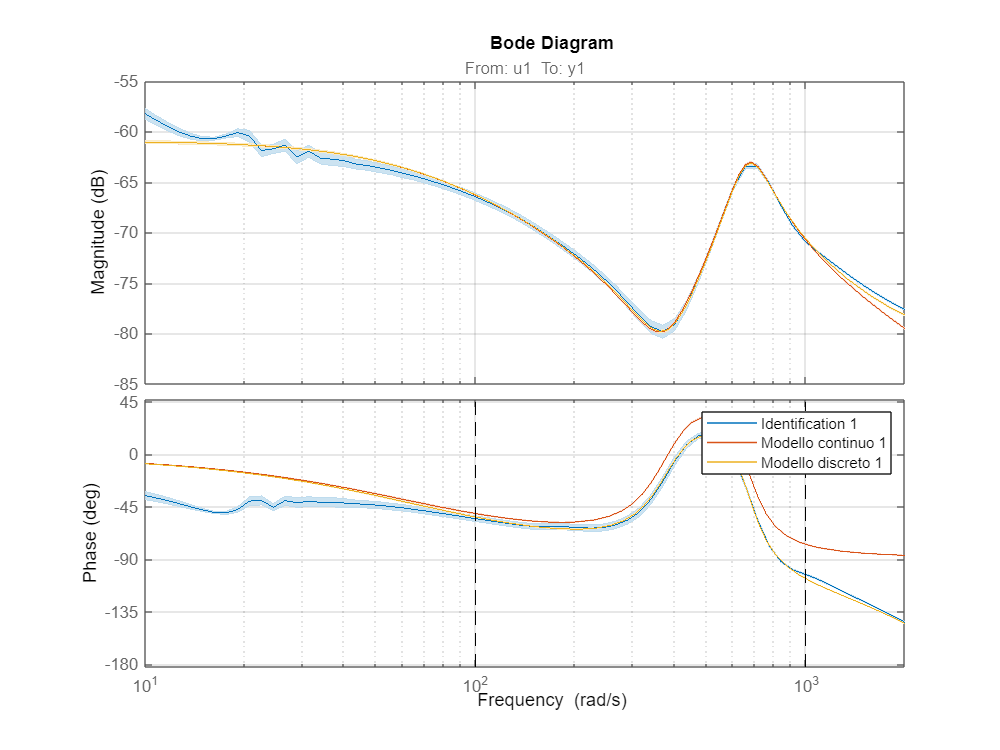

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase

h = bodeplot(freq_resp_ident_q1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_q1,modello_discreto_q1, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([wpeso1_1 wpeso1_1],ylim,'--k')
plot([wpeso1_2 wpeso1_2],ylim,'--k')

grid on
xlim([10 2e3]) %limite range di freq plottato

legend('Identification 1','Modello continuo 1','Modello discreto 1')

### Giunto 2

Vengono inseriti dei pesi per effettuare il fitting nelle frequenze di interesse, in particolare tra 250 rad/s e 900 rad/s.

peso = ones(length(freq_resp_ident_q2.Frequency),1);

wpeso2_1 = 250;
wpeso2_2 = 1000;

peso(freq_resp_ident_q2.Frequency<wpeso2_1) = 1e-3;
peso(freq_resp_ident_q2.Frequency>wpeso2_2) = 1e-3;   

Stima dei modelli continuo e discreto del secondo giunto.

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_q2 = ssest(freq_resp_ident_q2,5,opts);
modello_discreto_q2 = ssest(freq_resp_ident_q2,5,'Ts',st,opts);

Confronto con la risposta in frequenza del secondo giunto

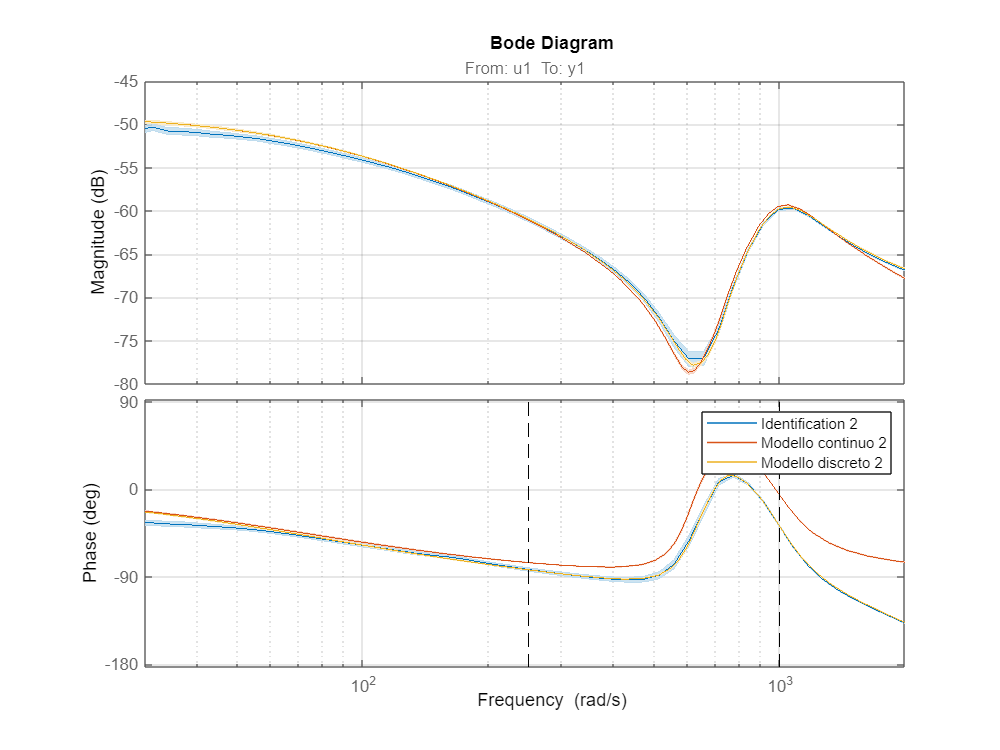

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase

h=bodeplot(freq_resp_ident_q2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_q2,modello_discreto_q2, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([wpeso2_1 wpeso2_1],ylim,'--k')
plot([wpeso2_2 wpeso2_2],ylim,'--k')


hold off
grid on
xlim([30 2e3]) %limite range di freq plottato

legend('Identification 2','Modello continuo 2','Modello discreto 2')

## Definizione segnale di validazione

Per la validazione è stato selezionato un segnale composto come nel caso precedente da chirp e portante, ma utilizzando parametri diversi.

Definisco la frequenza e l'ampiezza della portante rispettivamente pari a 2 rad/s e 130 Nm.

omega_portante_v=2;
ampiezza_portante_v=130;
T_portante_v=2*pi/omega_portante_v;

t_v=(0:st:(1.1*T_portante_v))';
portante_v=ampiezza_portante_v*sin(omega_portante_v*t_v);

Vengono definti la frequenza iniziale, finale e l'ampiezza del segnale chirp rispettivamente pari a 20 rad/s, 3141 rad/s e 300 Nm. La frequenza iniziale è stata selezionata come 10 volte quella della portante, mentre quella finale pari a pi-greco diviso il tempo di campionamento.

Un incremento quadratico per la frequenza del chirp è stato selezionato.

w0_v=omega_portante_v*10; %rad/s
w1_v=pi/st; %rad/s
control_action_validazione = chirp(t_v,w0_v/2/pi,t_v(end),w1_v/2/pi, 'quadratic');
ampliezza_validazione=300;
control_action_v = portante_v + control_action_validazione*ampliezza_validazione;

Confronto lo spettro del segnale di identificazione e validazione.

figure
title("Identificazione")
pspectrum(control_action,1/st,'spectrogram');

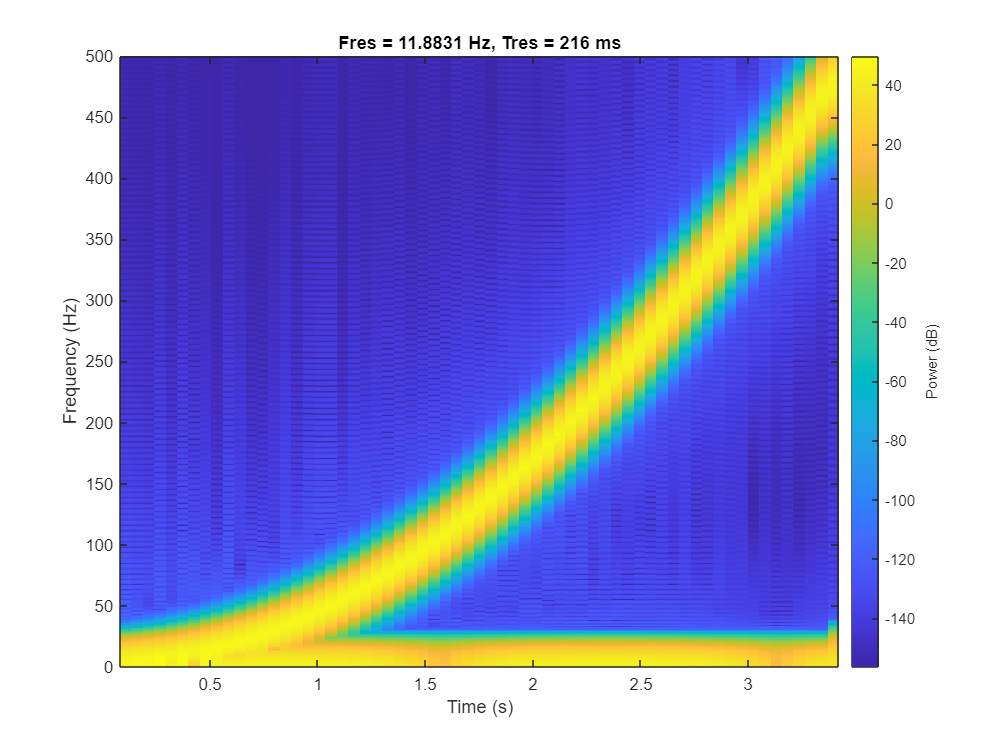

figure
title("Validazione")
pspectrum(control_action_v,1/st,'spectrogram');

#### Simulazione Giunto 1 Segnale Validazione

Definisco il segnale eccitante come il chirp sommato alla portante definiti prima per il giunto 1, mentre nullo per il giunto 2.

exciting_signal_q1_v = zeros(length(t_v),model.getInputNumber);
exciting_signal_q1_v(:,1) = control_action_v;

Simulo il sistema in anello chiuso per la validazione del giunto 1.

cs.initialize 
for idx=1:length(t_v)
    [process_output_q1_v(idx,:),control_action_q1_v(idx,:),t_q1_v(idx,1)]=cs.step(reference_cl(idx,:)',exciting_signal_q1_v(idx,:)');  
end


#### Simulazione Giunto 2 Segnale Validazione

Definisco il segnale eccitante come il chirp sommato alla portante definiti prima per il giunto 2, mentre nullo per il giunto 2.

exciting_signal_q2_v = zeros(length(t_v),model.getInputNumber);
exciting_signal_q2_v(:,2) = control_action_v;

Simulo il sistema in anello chiuso per la validazione del giunto 2.

cs.initialize 
for idx=1:length(t_v)
    [process_output_q2_v(idx,:),control_action_q2_v(idx,:),t_q2_v(idx,1)]=cs.step(reference_cl(idx,:)',exciting_signal_q2_v(idx,:)');  
end

#### Risposta in frequenza Validazione

#### Giunto 1

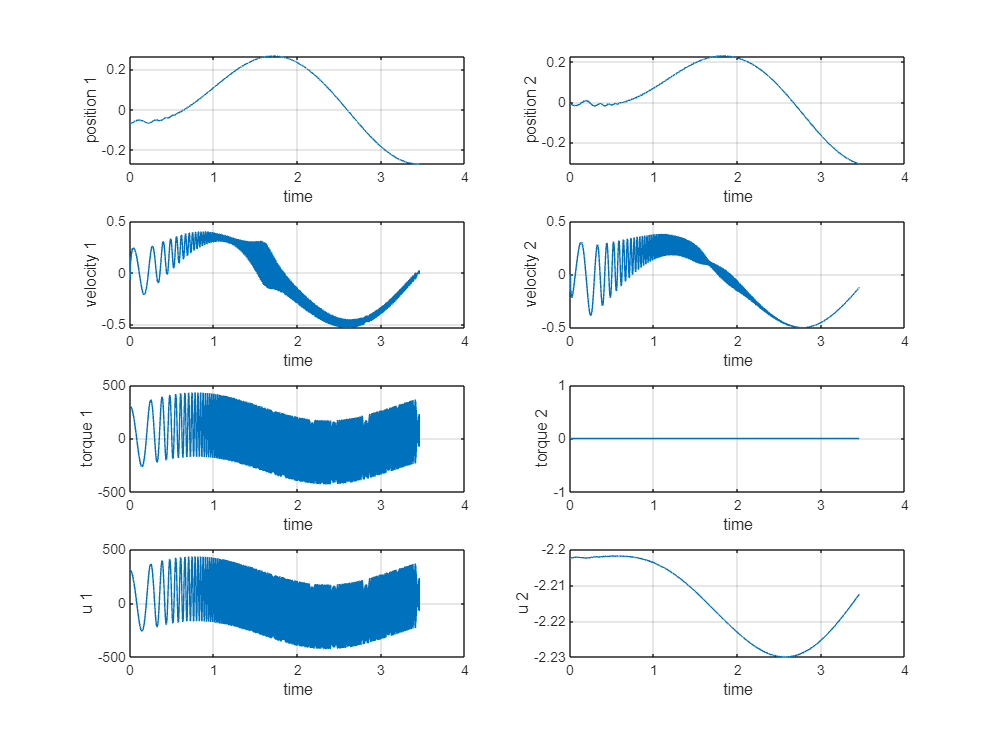

validation_q1 = iddata(process_output_q1_v(:,3),control_action_q1_v(:,1),st);
freq_resp_validazione_q1 = spafdr(validation_q1);
figure
subplot(4,2,1)
plot(t_q1_v,process_output_q1_v(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_q1_v,process_output_q1_v(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_q1_v,exciting_signal_q1_v(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_q1_v,control_action_q1_v(:,1))
xlabel('time')
ylabel('u 1')
grid on

subplot(4,2,2)
plot(t_q1_v,process_output_q1_v(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_q1_v,process_output_q1_v(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_q1_v,exciting_signal_q1_v(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_q1_v,control_action_q1_v(:,2))
xlabel('time')
ylabel('u 2')
grid on

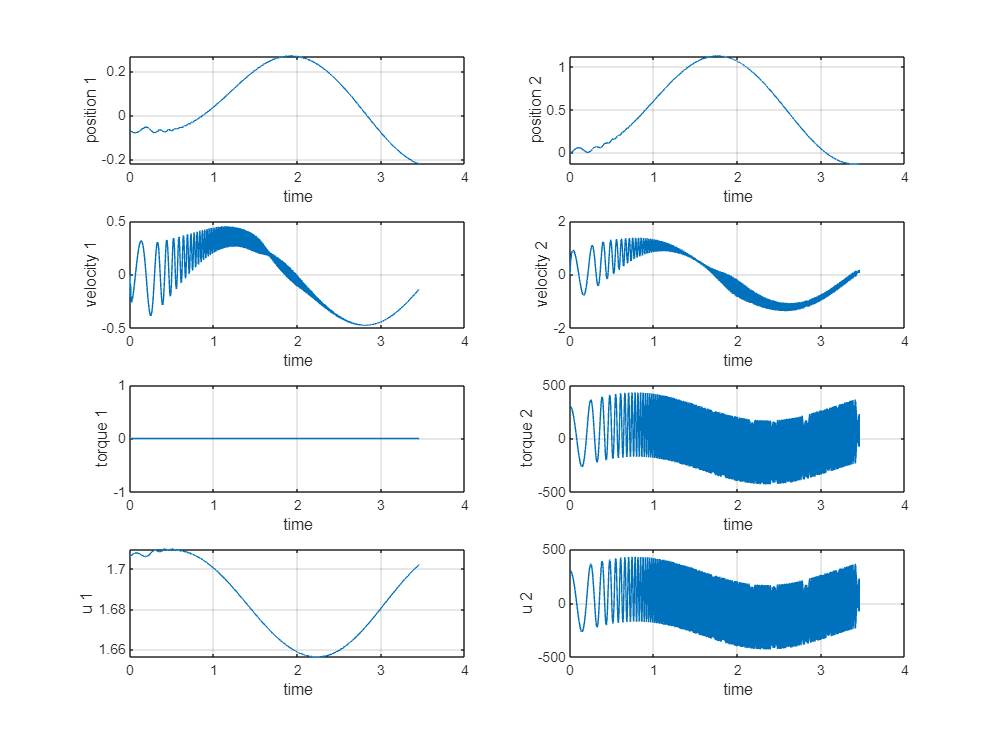

validation_q2 = iddata(process_output_q2_v(:,4),control_action_q2_v(:,2),st);
freq_resp_validazione_q2 = spafdr(validation_q2);
figure
subplot(4,2,1)
plot(t_q2_v,process_output_q2_v(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_q2_v,process_output_q2_v(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_q2_v,exciting_signal_q2_v(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_q2_v,control_action_q2_v(:,1))
xlabel('time')
ylabel('u 1')
grid on

subplot(4,2,2)
plot(t_q2_v,process_output_q2_v(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_q2_v,process_output_q2_v(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_q2_v,exciting_signal_q2_v(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_q2_v,control_action_q2_v(:,2))
xlabel('time')
ylabel('u 2')
grid on

#### Diagramma di bode della risposta in frequenza

La linea tratteggiata rossa rappresenta la frequenza iniziale del chirp.

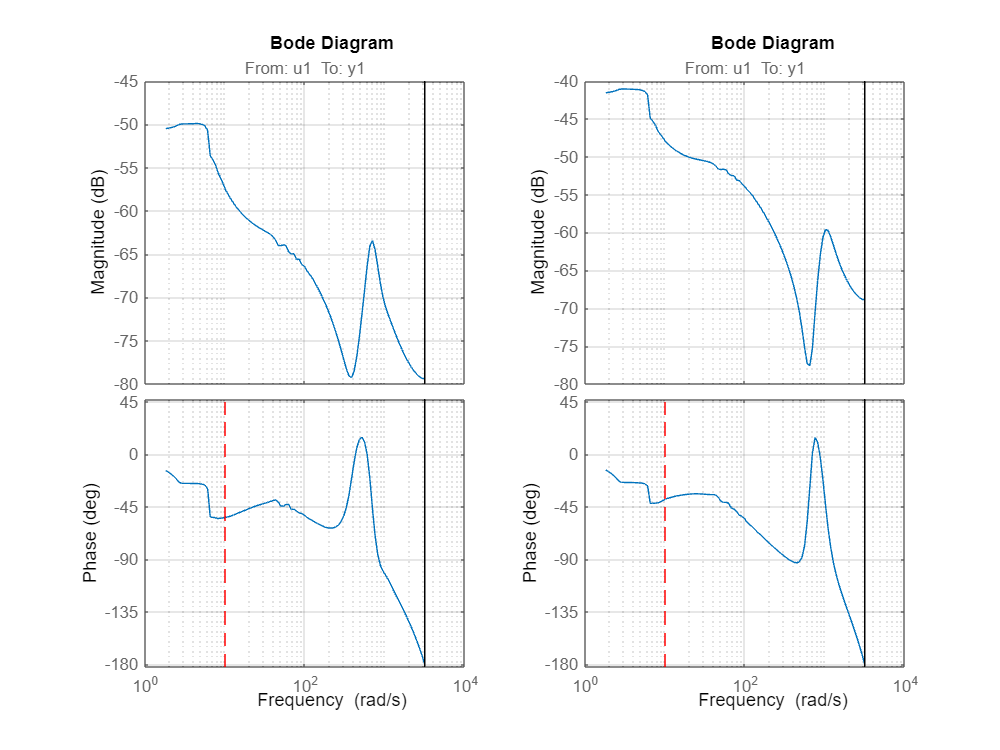

figure
subplot(1,2,1)
bode(freq_resp_validazione_q1)
hold on
plot(w0*[1 1],ylim,'--r') % frequenza iniziale del chirp
hold off
grid on

subplot(1,2,2)
bode(freq_resp_validazione_q2)
hold on
plot(w0*[1 1],ylim,'--r') % frequenza iniziale del chirp
hold off
grid on

## Confronto validazione e identificazione close loop

#### Giunto 1

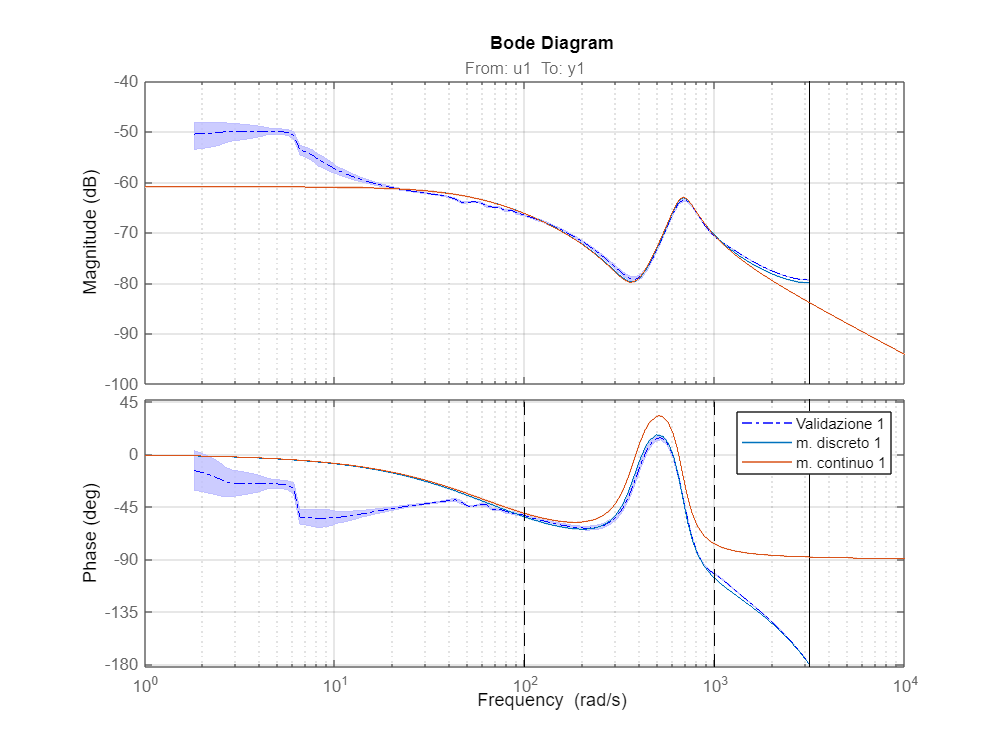

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_validazione_q1,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_discreto_q1, bode_opts)
bode(modello_continuo_q1, bode_opts)
plot([wpeso1_1 wpeso1_1],ylim,'--k')
plot([wpeso1_2 wpeso1_2],ylim,'--k')
grid on

legend('Validazione 1','m. discreto 1','m. continuo 1')

Paragone tra risposta in frequenza in identificazione e in validazione giunto 1.

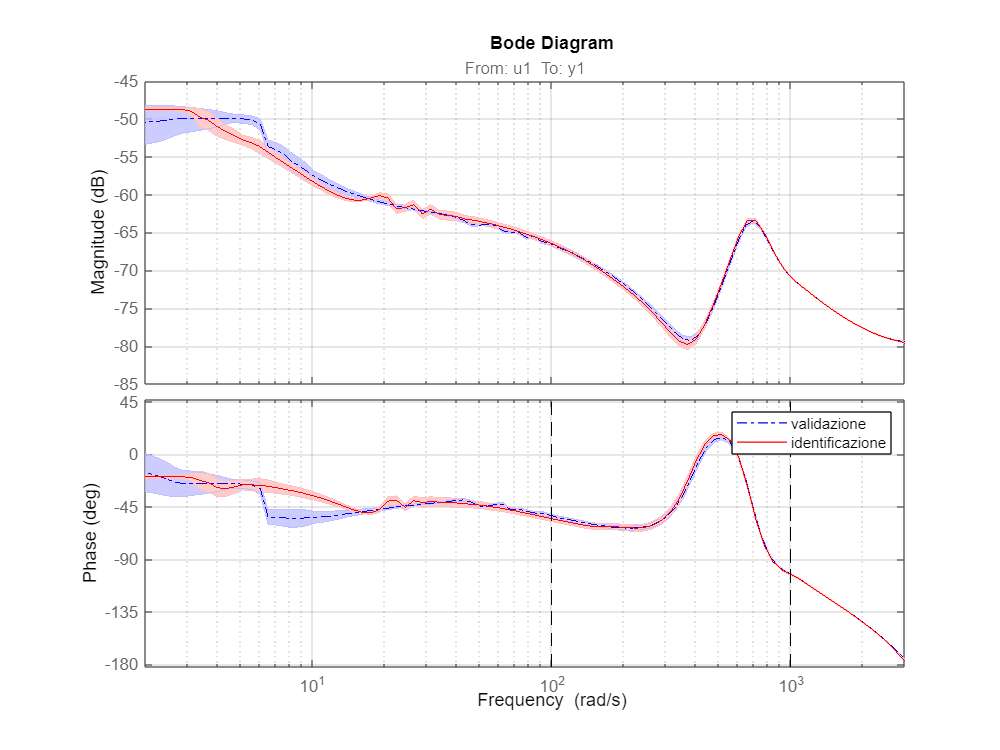

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_validazione_q1,'b-.', bode_opts);
showConfidence(h,3)
hold on
bode(freq_resp_ident_q1, bode_opts,'r')
plot([wpeso1_1 wpeso1_1],ylim,'--k')
plot([wpeso1_2 wpeso1_2],ylim,'--k')
grid on

legend('validazione','identificazione')
xlim([2 3e3])

#### Giunto 2

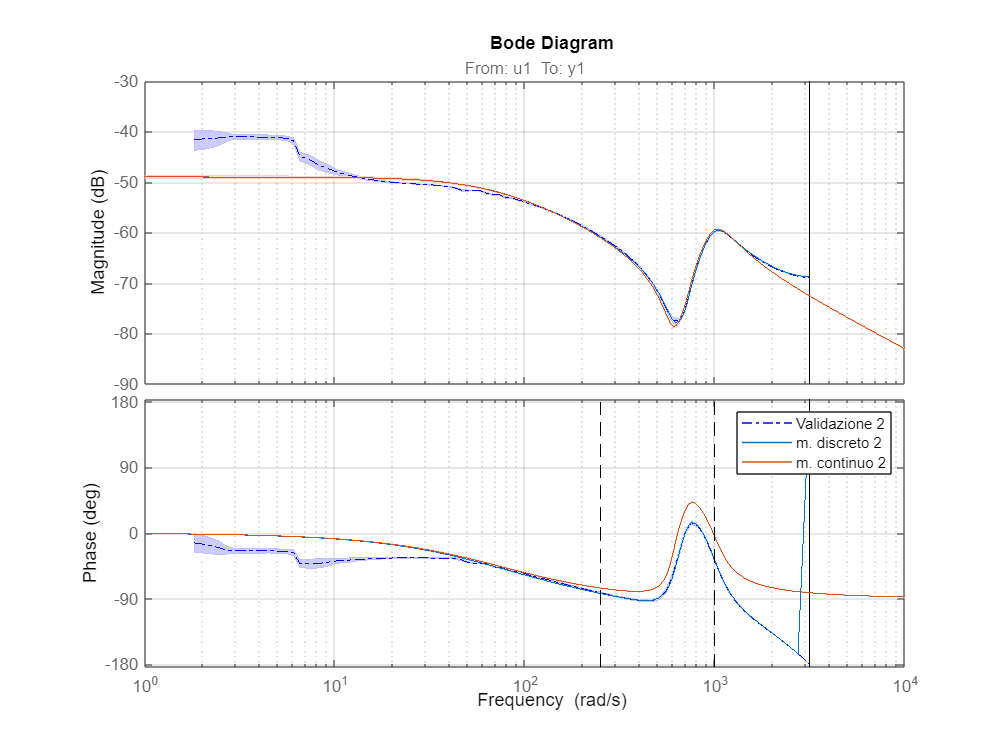

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_validazione_q2,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_discreto_q2, bode_opts)
hold on
bode(modello_continuo_q2, bode_opts)
hold on 
plot([wpeso2_1 wpeso2_1],ylim,'--k')
hold on
plot([wpeso2_2 wpeso2_2],ylim,'--k')
grid on

legend('Validazione 2','m. discreto 2','m. continuo 2')

Paragone tra risposta in frequenza in identificazione e in validazione giunto 2.

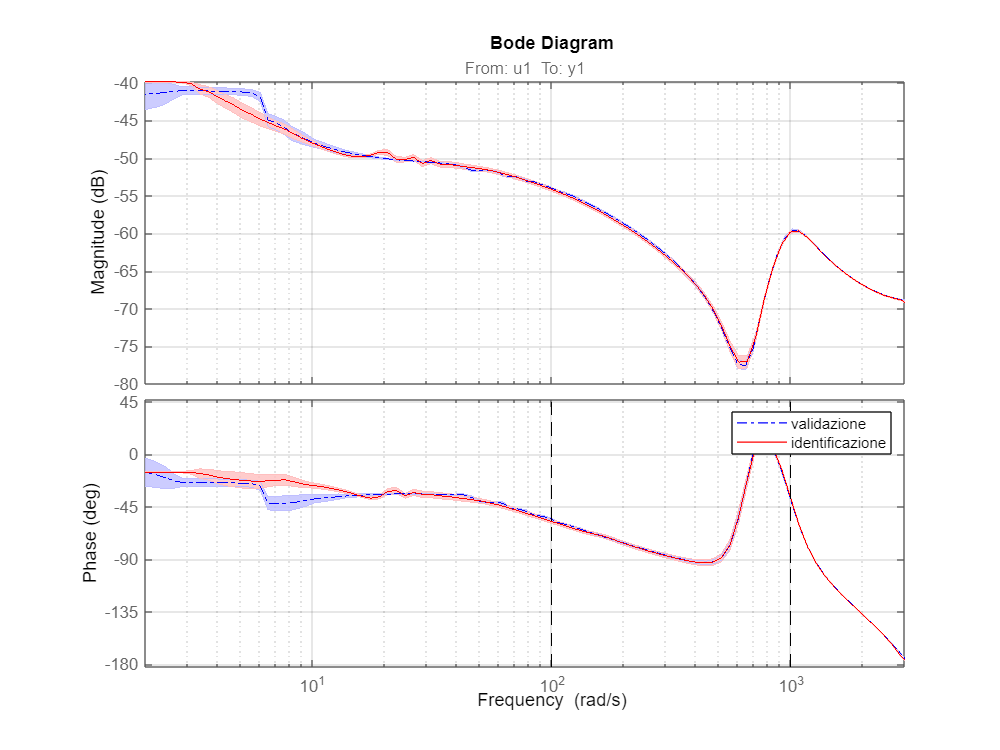

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_validazione_q2,'b-.', bode_opts);
showConfidence(h,3)
hold on
bode(freq_resp_ident_q2, bode_opts,'r')
plot([wpeso1_1 wpeso1_1],ylim,'--k')
plot([wpeso1_2 wpeso1_2],ylim,'--k')
grid on

legend('validazione','identificazione')
xlim([2 3e3])